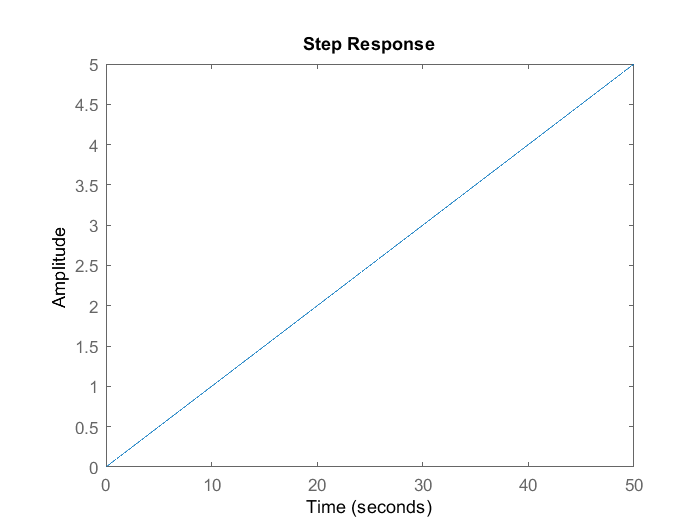

%%  Step response of Transfer function 1/(10s)
num = 1;
den = [10 0];
g2 = tf(num,den);
figure(13)
step(g2);

stepinfo(g2)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


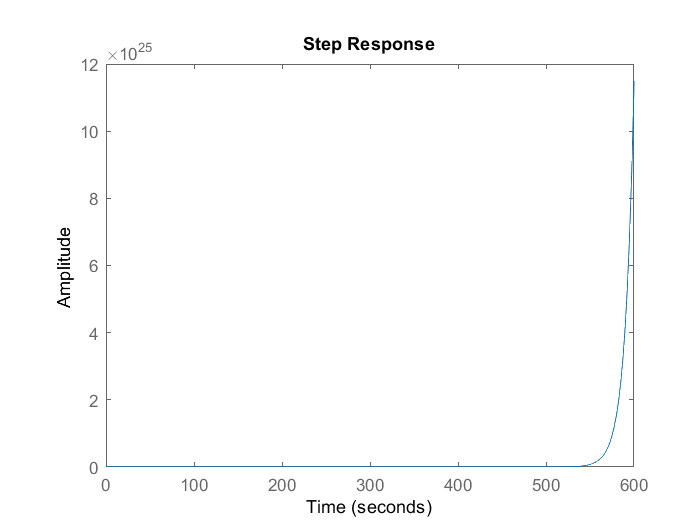

%% Step response of g2 with positive(1) feedback
n = feedback(g2,1,1);
figure(14)
step(n);

stepinfo(n)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


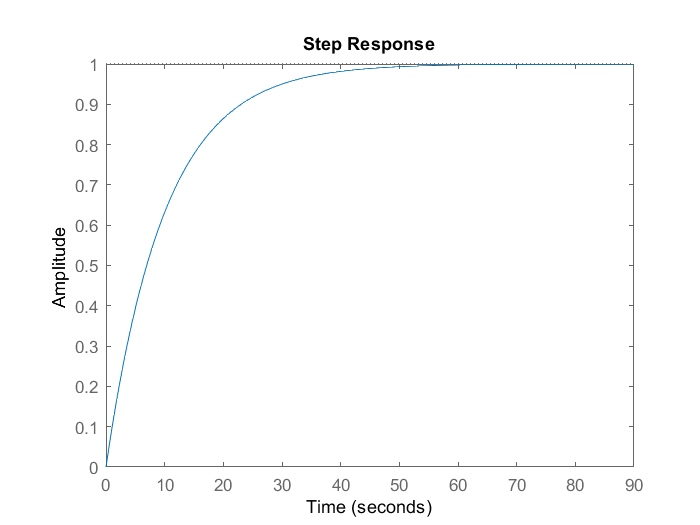

%% Step response of g2 with negative(1) feedback
n1 = feedback(g2,1);
figure(15)
step(n1);

stepinfo(n1)

ans = struct with fields:
        RiseTime: 21.9701
    SettlingTime: 39.1207
     SettlingMin: 0.9045
     SettlingMax: 1.0000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.0000
        PeakTime: 105.4584


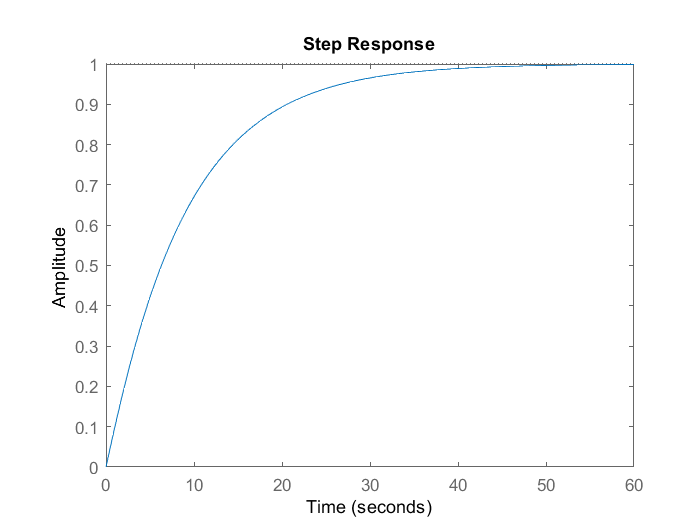


%% step response of g2 with s+1 pole in -ve feedback path
h1 = tf(1,[1 1]);
n2 = feedback(g2,h1);
figure(16)
step(n2);

stepinfo(n2)

ans = struct with fields:
        RiseTime: 19.5623
    SettlingTime: 34.8576
     SettlingMin: 0.9029
     SettlingMax: 0.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9993
        PeakTime: 64.9699


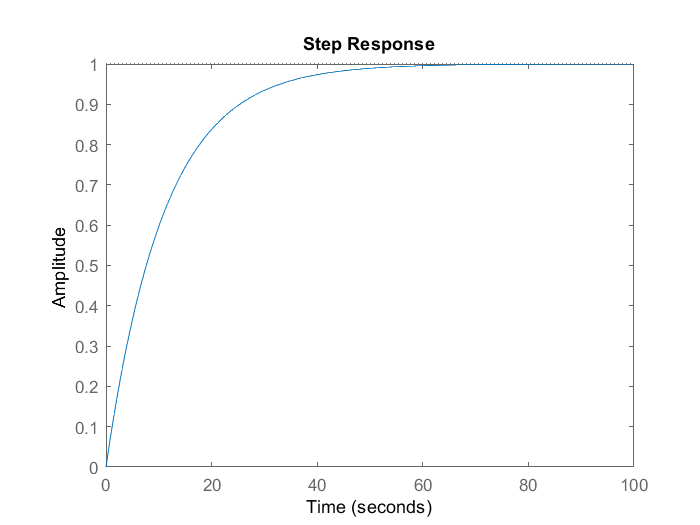

%% step response of g with s+1 zero in -ve feedback path
h2 = tf([1 1],1);
n3 = feedback(g2,h2);
figure(17)
step(n3);

stepinfo(n3)

ans = struct with fields:
        RiseTime: 24.1671
    SettlingTime: 43.0328
     SettlingMin: 0.9045
     SettlingMax: 1.0000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.0000
        PeakTime: 116.0042


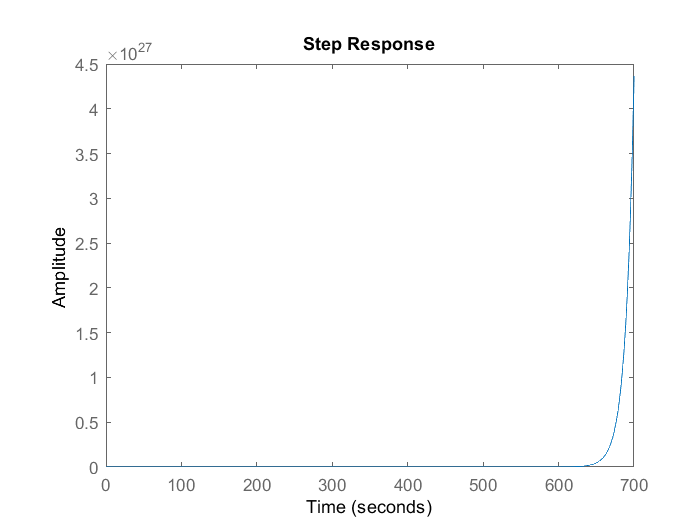

%% step response of g with s-1 zero in -ve feedback path
h3 = tf([1 -1],1);
n4 = feedback(g2,h3);
figure(18)
step(n4);

stepinfo(n4)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf
